# MP1-Worst Case Analysis

### Jiayuan Liu

The idea of this algorithm is to find the points at around the same location (called 'period points') on different cycles in order to find the average period of one simulated solution (there are 8 solutions in total since there 7 component tolerance in the parameter sweep.)

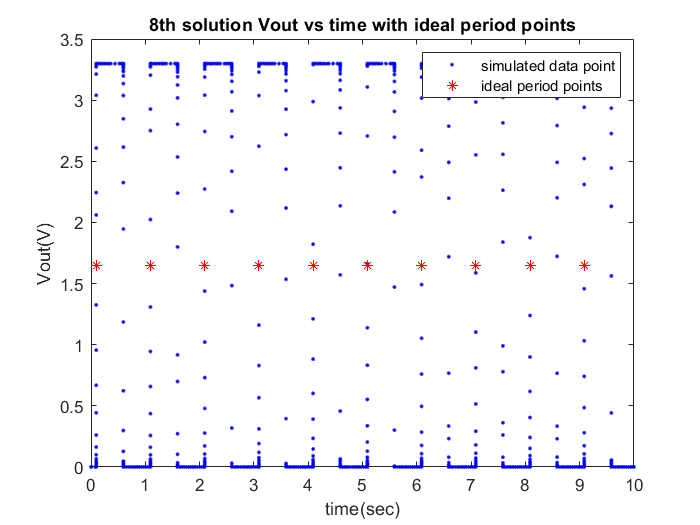

clear
% load data from LTSpice
loadspice("MP_now.txt")
period_lst = [];
V_intersect = 1.65;

% repeated for all 8 solutions
for i = 1:length(time)
    % Extract matrix of each wave
    cell_time = time(i);
    time_i = cell_time{1};
    cell_vout = vout(i);
    vout_i = cell_vout{1};
    ptime_ = [];
    pv = [];
    for j = 3:1:length(vout_i)
        % Find two points around a horizontal line for each cycle
        if vout_i(j) >= V_intersect && vout_i(j-1) <= V_intersect
            % Averaging the two points to estimate the intersection with
            % the horizontal line -- the intersection is 'period point'
            ptime_(end+1) = mean([time_i(j), time_i(j-1)]);
            ptime = ptime_(2:end);
            pv(end+1) = mean([vout_i(j),vout_i(j-1)]);
            % Average the time elapsed between every two period points
            period = mean(diff(ptime));
            period_lst(end+1) = period;
        end
    end
end
% Ideal period points on square waves
figure(1)
plot(time_i, vout_i,"b.", ptime_, V_intersect * ones(length(ptime_)),"r*"); 
legend("simulated data point", "ideal period points")
title("8th solution Vout vs time with ideal period points")
xlabel("time(sec)")
ylabel("Vout(V)")

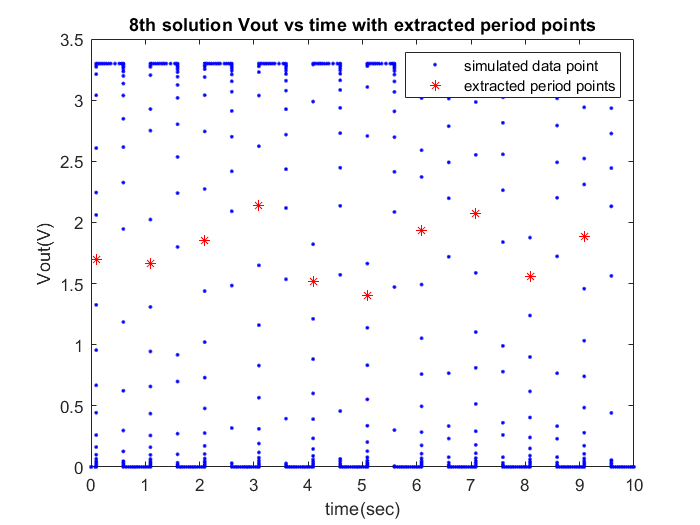


% Actual period points extracted on square waves
% The period points are not exactly at the same location on the 10 cycles,
% but given that the square waves are mostly vertical, the time difference is negligible.

figure(2)
plot(time_i, vout_i,"b.", ptime_, pv,"r*"); 
title("8th solution Vout vs time with extracted period points")
legend("simulated data point", "extracted period points")
xlabel("time(sec)")
ylabel("Vout(V)")

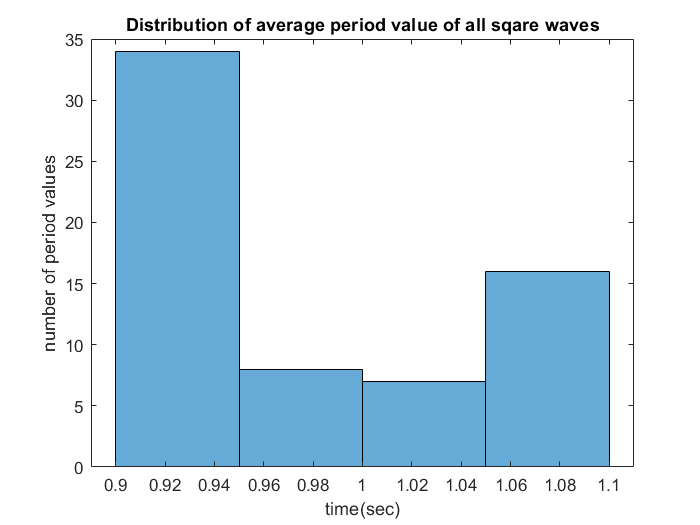


% Histogram of periods on all sqare waves
figure(3)
histogram(period_lst)
title("Distribution of average period value of all sqare waves")
xlabel("time(sec)")
ylabel("number of period values")